## **Finite Element Method**

clc; 
clear;
syms x f(x) u_e(x) h



% OIF Order of Interpolation Function foe element
OIF =1

OIF = 1

% No of elements
e = 5;

a=1

a = 1

b = 5

b = 5

c =x

$$c = x$$

f(x) = 4*x^2 - 2*x -4;


%----------------------------------------------------------------------------
deqn = a*diff(u_e,x,2)+b*diff(u_e,x,1)+c*u_e == f;

Value1 = 0;
Value2 = 1;

ic = u_e(0) == Value1;
d_ue(x)= diff(u_e,x);
%ic2 = d_ue(1) == Value2;
ic2=u_e(1) == Value2;

u_exact = dsolve(deqn,[ic ic2]);
exact_sol_f = u_exact;
%----------------------------------------------------------------------------------



% domain of X
x0 = 0;
xn = 1;
% Element length
h_num = (xn - x0) / e;





[phi_e,nLP,Difference] = ShapeFunctions(OIF) % Gives shape functions and No of Nodal points for element

$$phi\_e = \left(\begin{array}{cc} \frac{h-x}{h} & \frac{x}{h} \end{array}\right)$$

nLP = 2

$$Difference = h$$


Difference = subs(Difference,h,h_num) 

$$Difference = \frac{1}{5}$$


% At nodel point the value of x
X = (x0:Difference:xn)';






% Local stiffness matrix
KL1 = zeros(nLP, nLP, 'sym');
KL2 = zeros(nLP, nLP, 'sym');
KL3_Ten3 = zeros(nLP, nLP,nLP, 'sym');
F_Mat = zeros(nLP, nLP, 'sym');

for i = 1:nLP
    for j = 1:nLP
        for K = 1:nLP
            KL3_Ten3(i, j,K) = int(-1 * phi_e(i) * phi_e(j)* phi_e(K), x, 0, h);
        end
        KL1(i, j) = int(a * diff(phi_e(i), x) * diff(phi_e(j), x), x, 0, h);
        KL2(i, j) = int(-b * diff(phi_e(j), x) * phi_e(i), x, 0, h);
        % Because of this B term This Cannot be Bilinear proper indexing is
        % Must, play with i and j in KL2 to get Correct answer
        F_Mat(i, j) = int(-1* phi_e(i) * phi_e(j), x, 0, h);
    end
end



% Substitute values into the local  matrices
KL1_sub = subs(KL1, h, h_num);
KL2_sub = subs(KL2, h, h_num);
KL3_Ten3_sub = subs(KL3_Ten3, h, h_num);
F_Mat_sub = subs(F_Mat, h, h_num);

%generl formula for finding size of gloabl stiffness matrix-(S=OIF*e+1
S=OIF*e+1;

global_matrix_size = S; % each element has 2 nodal points
% Initialize global stiffness matrix

KL1_global = zeros(global_matrix_size);
KL2_global = zeros(global_matrix_size);
KL3_Ten3_global = zeros(global_matrix_size,global_matrix_size,global_matrix_size);
F_global = zeros(global_matrix_size);

% Loop through each element
for element = 1:nLP-1:S-1

    % Assemble local stiffness matrix into global stiffness matrix
    start_index = element;
    end_index = element + nLP-1;
    KL1_global(start_index:end_index, start_index:end_index) = KL1_global(start_index:end_index, start_index:end_index) + KL1_sub;
    KL2_global(start_index:end_index, start_index:end_index) = KL2_global(start_index:end_index, start_index:end_index) + KL2_sub;
    KL3_Ten3_global(start_index:end_index, start_index:end_index,start_index:end_index) = KL3_Ten3_global(start_index:end_index, start_index:end_index,start_index:end_index) + KL3_Ten3_sub;


    F_global(start_index:end_index, start_index:end_index) = F_global(start_index:end_index, start_index:end_index) + F_Mat_sub;
end

c_x = sym(zeros(S, 1));
f_x = sym(zeros(S, 1));

for i = 1:S
    f_x(i) = subs(f, x, X(i));
    c_x(i) = subs(c, x, X(i));
end



% Perform tensor-vector multiplication
KL3_global = zeros(global_matrix_size); % Initialize the result tensor
for i = 1:global_matrix_size

    for j = 1:global_matrix_size

        for k = 1:global_matrix_size

            KL3_global(i, j) = KL3_global(i, j) + KL3_Ten3_global(i, j, k) * c_x(k);
        end
    end
end

%K_global_inverse=InverseTDMA(K_global)

Fv = F_global*f_x;

du_dx = -3;

% Dirichlet Boundary Conditions

K_global_D_bc = KL1_global+KL2_global+KL3_global;
g_x_D_bc = sym(zeros(S, 1));
GNM_D_bc= a*g_x_D_bc*du_dx;
RHS_D_bc = GNM_D_bc+Fv;

% Boundary Conditions1
u0 = Value1;
K_global_D_bc(1,:)= [1,zeros(1, S-1)];  %u0 = 0
RHS_D_bc(1) = u0;  % RHS of equation

% Boundary Conditions2
un = Value2;
K_global_D_bc(end,:)= [zeros(1, S-1), 1];  %un=-1
RHS_D_bc(end) = un;  % RHS of equation

% % for finding inverse I'm using My TDMA inverse function
% K_global_D_bc_inverse=InverseTDMA(K_global_D_bc);

%The Solution of Dirichlet B.C. using FEM is =
u_D_bc = double(K_global_D_bc\RHS_D_bc);% u at nodal points
disp("-------------------------------------------------------------")

-------------------------------------------------------------


disp("The Solution of Dirichlet B.C. using FEM is")

The Solution of Dirichlet B.C. using FEM is


myTable = table(X, u_D_bc, 'VariableNames', {'Nodal point', 'u'});
disp(myTable);

    Nodal point      u   
    ___________    ______

        0               0
        1/5        1.0807
        2/5        1.3237
        3/5        1.2814
        4/5        1.1483
        1               1



disp("-------------------------------------------------------------")

-------------------------------------------------------------


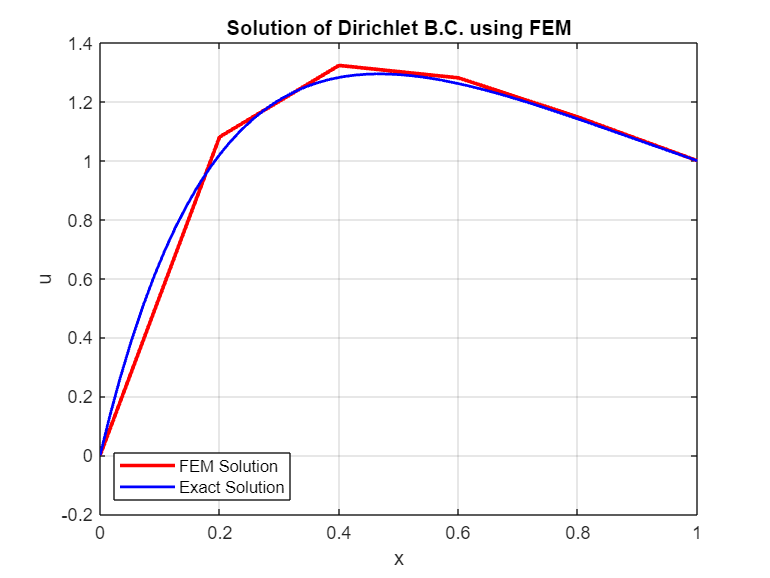

%Plot the FDM Solution and the actual solution
figure;
plot(X, u_D_bc, "r", "LineWidth", 2, "DisplayName", "FEM Solution"); 
hold on;
fplot(x, exact_sol_f, [0 1], "b", "LineWidth", 1.5, "DisplayName", "Exact Solution");
xlabel("x");
ylabel("u");
title("Solution of Dirichlet B.C. using FEM");
legend('Location', 'southwest');
grid on;

function [N_sub,n,Differe] = ShapeFunctions(OIF)  % Gives shape functions and No of Nodal points for element
    syms x h;
    % OIF Order of Interpolation Function foe element
    % No of sub elements in element
    e = OIF;
    % No of Nodal points in element
    n =e+1; 
    
    x_local = sym(zeros(1, n)); % Initialize vector with zeros
    % Local Nodel points for element
    Differe = 0;
    for i = 1:n
        x_local(i) = (i-1)*h/e; % Calculate the elements of the vector
        if i ==2
        Differe = (i-1)*h/e;
        end
    end
    
    %disp(x_local); % Display the vector
    
    x_string = sym('x', [1 n]);
    
    N = sym(zeros(size(x_string)));
    
    % Generating Lagrange interpolating polynomial
    for j = 1:n
        % Compute the product term for each j
        product_term = 1;
        for k = 1:n
            if k ~= j
                product_term = product_term * (x - x_string(k)) / (x_string(j) - x_string(k));
            end
        end
    
        N(j)=product_term;
    end
    
    N_sub = subs(N,x_string,x_local);
end


